% Using edfread
route = 'C:\Users\pawel\Downloads\beta-divergence-based-recurrence-plots-for-audio-time-series-analysis-master\beta-divergence-based-recurrence-plots-for-audio-time-series-analysis-master\chb-mit-scalp-eeg-database-1.0.0\chb-mit-scalp-eeg-database-1.0.0\chb20\chb20_15.edf'

route = 'C:\Users\pawel\Downloads\beta-divergence-based-recurrence-plots-for-audio-time-series-analysis-master\beta-divergence-based-recurrence-plots-for-audio-time-series-analysis-master\chb-mit-scalp-eeg-database-1.0.0\chb-mit-scalp-eeg-database-1.0.0\chb20\chb20_15.edf'

[data, header] = edfread(route);

all_data = cell2mat(table2cell(data));

% Apply detrend to each channel
myCluster = parcluster('Processes');  
delete(myCluster.Jobs);
data_detrended = detrend(all_data); % Automatically detrends each column separately
number_of_channels = 12;

% Normalize Data
normalizedData = zeros(size(data_detrended));

parfor i = 1:number_of_channels
    normalizedData(:,i) = normalize(data_detrended(:,i));
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.



% Shift everything to be non-negative


fs = 256;

function filtered_signal = bandpass_filter(data, lowcut, highcut, fs)
    % Design the Butterworth bandpass filter
    [b, a] = butter(4, [lowcut, highcut] / (fs / 2), 'bandpass'); 
    filtered_signal = filtfilt(b, a, data);  % Apply the filter
end

% Apply bandpass filters to each frequency range
delta  = bandpass_filter(normalizedData, 0.5, 4, fs);   % Delta: 0.5–4 Hz
theta  = bandpass_filter(normalizedData, 4, 8, fs);     % Theta: 4–8 Hz
alpha  = bandpass_filter(normalizedData, 8, 13, fs);    % Alpha: 8–12 Hz
beta   = bandpass_filter(normalizedData, 13, 30, fs);   % Beta: 12–30 Hz

delta = delta - min(delta, [], 1);
theta = theta - min(theta, [], 1);
alpha = alpha - min(alpha, [], 1);
beta = beta - min(beta, [], 1);
normalize_01 = @(x) (x - min(x, [], 1)) ./ max((max(x, [], 1) - min(x, [], 1)), eps);
delta  = normalize_01(delta);
theta  = normalize_01(theta);
alpha  = normalize_01(alpha);
beta   = normalize_01(beta);

time_frame = [410,416];

wanted_alpha = alpha((time_frame(1) * 256) + 1 : time_frame(2) * 256, :);
wanted_beta = beta((time_frame(1) * 256) + 1 : time_frame(2) * 256, :);
wanted_theta = theta((time_frame(1) * 256) + 1 : time_frame(2) * 256, :);
wanted_delta = delta((time_frame(1) * 256) + 1 : time_frame(2) * 256, :);



m = 4;
t = 4;
num_channels = 4;  % Number of columns (channels)

% Run once to get the size of an RM (assuming fixed size)
sample_rm = computeRM_blockedkronecker_nonsymmetric(wanted_alpha(:, 1), m, t, 100, 1.8);
% Preallocate a logical 3D array (fastest)
[N, M] = size(sample_rm);  % Get matrix size
recurrence_alpha = zeros(N, M, num_channels);
recurrence_beta = zeros(N, M, num_channels);
recurrence_delta = zeros(N, M, num_channels);
recurrence_theta = zeros(N, M, num_channels);

% Compute recurrence matrices in a loop
parfor i = 1:num_channels
    disp(i);
    recurrence_alpha(:, :, i) = computeRM_blockedkronecker_nonsymmetric(wanted_alpha(:, i), m, t, 100, 1.6);
    recurrence_beta(:, :, i) = computeRM_blockedkronecker_nonsymmetric(wanted_beta(:, i), m, t, 100, 1.6);
    recurrence_delta(:, :, i) = computeRM_blockedkronecker_nonsymmetric(wanted_delta(:, i), m, t, 100, 1.6);
    recurrence_theta(:, :, i) = computeRM_blockedkronecker_nonsymmetric(wanted_theta(:, i), m, t, 100, 1.6);
end

     4

     3

     1

     2



varia = 2;
thresh_hold_alphas = zeros(N, M, num_channels);
thresh_hold_betas = zeros(N, M, num_channels);
thresh_hold_deltas = zeros(N, M, num_channels);
thresh_hold_thetas = zeros(N, M, num_channels);
eps_alpha = varia * std(alpha,0,1);
eps_beta =  varia * std(beta,0,1);
eps_delta = varia * std(delta,0,1);
eps_theta = varia * std(theta,0,1);
parfor i = 1:num_channels
    thresh_hold_alphas(:,:,i) = recurrence_alpha(:, :, i)<eps_alpha(i);
    thresh_hold_betas(:,:,i) = recurrence_beta(:, :, i)<eps_beta(i);
    thresh_hold_deltas(:,:,i) = recurrence_delta(:, :, i)<eps_delta(i);
    thresh_hold_thetas(:,:,i) = recurrence_theta(:, :, i)<eps_theta(i);


end

thresh_hold_alpha = all(thresh_hold_alphas,3);
thresh_hold_beta = all(thresh_hold_betas,3);
thresh_hold_delta = all(thresh_hold_deltas,3);
thresh_hold_theta = all(thresh_hold_thetas, 3);

combined_alpha = mean(wanted_alpha, 2); % Average across the 23 channels
combined_beta = mean(wanted_beta, 2); % Average across the 23 channels
combined_delta = mean(wanted_delta, 2); % Average across the 23 channels
combined_theta = mean(wanted_theta, 2); % Average across the 23 channels


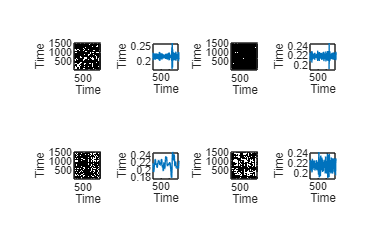

f = figure('Position', [100, 42, 1000, 600]);
colormap([0 0 0 ; 1 1 1]);

subplot(2,4,1);
imagesc(thresh_hold_alpha);
xlabel('Time');
ylabel('Time');
axis xy
axis tight
axis square

subplot(2,4,2);
plot(combined_alpha);
xlabel('Time');
ylabel('Time');
axis xy
axis tight
axis square

subplot(2,4,3);
imagesc(thresh_hold_beta);
xlabel('Time');
ylabel('Time');
axis xy
axis tight
axis square

subplot(2,4,4);
plot(combined_beta);
xlabel('Time');
ylabel('Time');
axis xy
axis tight
axis square

subplot(2,4,5);
imagesc(thresh_hold_delta);
xlabel('Time');
ylabel('Time');
axis xy
axis tight
axis square

subplot(2,4,6);
plot(combined_delta);
xlabel('Time');
ylabel('Time');
axis xy
axis tight
axis square

subplot(2,4,7);
imagesc(thresh_hold_theta);
xlabel('Time');
ylabel('Time');
axis xy
axis tight
axis square

subplot(2,4,8);
plot(combined_theta);
xlabel('Time');
ylabel('Time');
axis xy
axis tight
axis square


exportgraphics(f,'barchart.png')

